# Create List Items One at a Time

You can create a list by creating each item as an `mlreportgen.dom.ListItem` object and appending the object to an `mlreportgen.dom.UnorderedList` or an `mlreportgen.dom.OrderedList` object.

This example creates three `ListItem` objects and appends them to an `OrderedList` object. The first `ListItem object` consists of an `mlreportgen.dom.Text` object and an `mlreportgen.dom.Table` object. To generate an unordered list, change the `mlreportgen.dom.OrderedList` class to an `mlreportgen.dom.UnorderedList` class.

import mlreportgen.dom.*;
d = Document('unorderedListReport','html');

li1 = ListItem('Rank 3 magic square:');
table = append(li1,Table(magic(3)));
table.Border = 'inset';
table.Width = '1in';
li2 = ListItem('Second item');
li3 = ListItem('Third item');

ul = OrderedList();
append(ul,li1);
append(ul,li2);
append(ul,li3);

append(d,ul);

close(d);
rptview(d.OutputPath);

Here is the generated table:

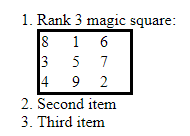

*Copyright 2019 The MathWorks, Inc.*